# Bright Beats Challenge - MATLAB Simulation

In this activity, you'll be turning brightness values extracted from a digital image into piano sounds! Earlier, you used a micro:bit to create a digital synthesizer that could transform ambient light levels and simple images into musical notes. The device you built empowered users to **"hear" light as sounds**, a tool that could be especially useful for those who are visually impaired**.** In this MATLAB activity, you will turn pixels from digital images into piano notes. In the process, you'll uncover the power of computers and programs like MATLAB for transforming visual and audio signals through **signal processing** and learn how images are represented by computers. Building upon the micro:bit activity with the power of MATLAB, you'll be able to customize the sounds further and translate more complex images into sounds.

### Overview

- **Part 1**: Translate stripes to sounds

- **Part 2**: Translate a grayscale image to sounds

- **Part 3**: Translate colors to sounds

- **Summary and Future Learning**

**Note**: By default, the lines of code underlying these activities have been hidden. However, if you'd like to peek under the hood and understand how each of these activities have been enabled by programming, you can toggle between different views using these buttons on the right hand toolstrip:

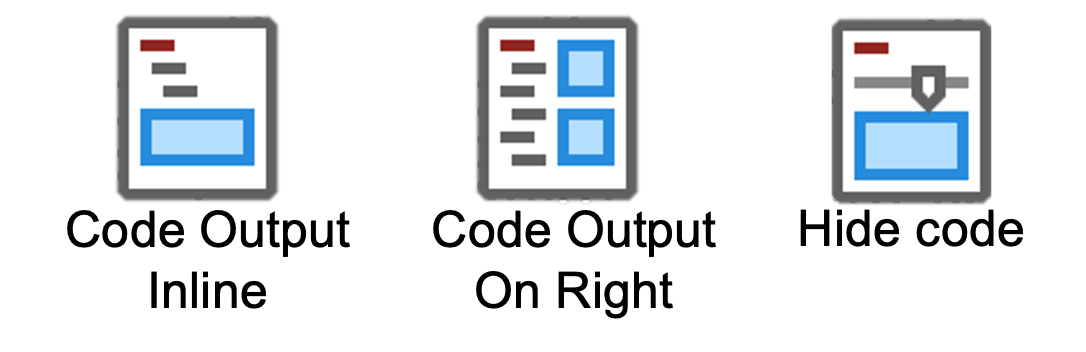

## Get Started

First, please choose a range of piano notes to use for this activity. Choose an octave from the drop down menu *or* use the default notes. Click 'Use default notes' to use them.

% This is a list of sound frequencies that correspond to each of the
% possible piano notes
frequencies = [130.81, 146.83, 164.81, 174.61, 196.00, 220.00, 246.94, 261.63;...
261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 532.25;...
523.25, 587.33, 659.25, 698.46, 783.99, 880.00, 987.77, 1046.5];

octave = 2;
frequencies = frequencies(octave,:); % Select a subset of frequencies based on the octave of notes chosen
disp('Submitted! Thank you for selecting the notes to use. Scroll down to continue.')
 

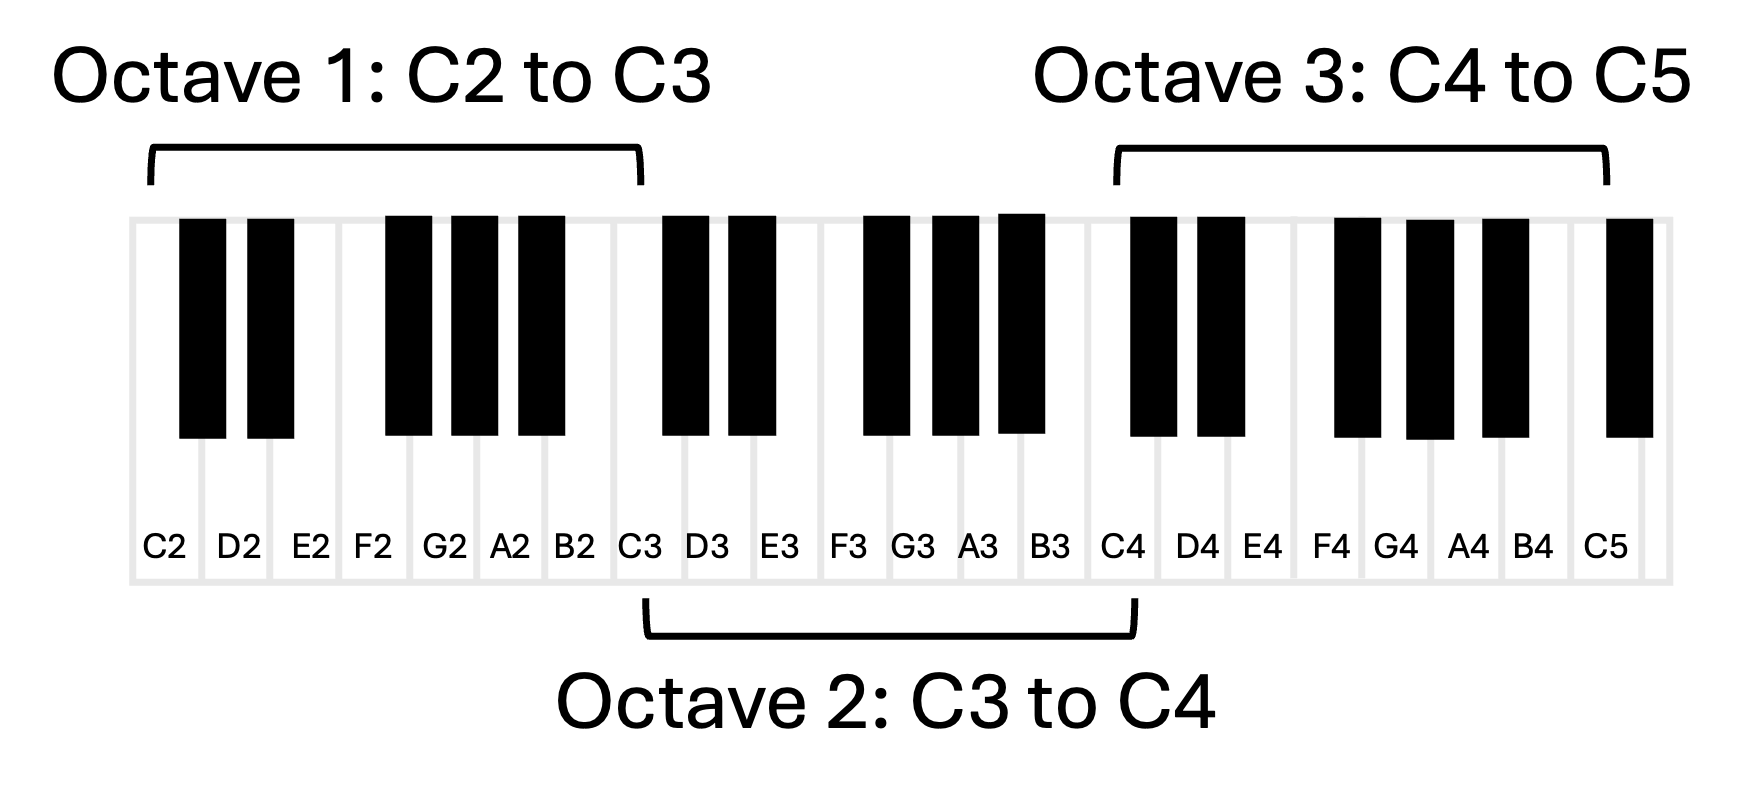

 
for k=1:length(frequencies)
    % This loop goes through each note in the chosen octave
    % 'k' is a number that starts at 1 and increases by 1 each time until it reaches the total number of notes.
    
    % Here, we create a time sequence that lasts for half a second.
    % The time is divided into very small parts (0.000125 seconds) so we can make smooth sounds.
    note_value=0:0.000125:0.5; 
    Fs = 14100; 
    
    % We make a sound wave using the frequency of the note we are currently on.
    % This wave is what we will hear when we play the sound.
    a = sin(2*pi*frequencies(k)*note_value); 

    % Now we play the sound we just created.
    sound(a, Fs)
    
    % We pause for 1 second so we can hear the sound clearly before moving on to the next one.
    pause(1) 
end

## Part 1: Translate stripes to sounds

Your micro:bit device 'translated' a black and white image to sounds, with different sounds representing black or white parts of the image. You can do the same thing in MATLAB.

First, let's generate a random image of black and white stripes. 

 
% Parameters
rng('shuffle');        % optional: seed from clock for randomness
minStripes = 5;        % minimum number of stripes
maxStripes = 10;       % maximum number of stripes
minWidth = 10;          % minimum stripe width in pixels
maxWidth = 40;         % maximum stripe width in pixels
height = 200;          % image height in pixels

% Choose random number of stripes
n = randi([minStripes, maxStripes]);

% Random widths
widths = randi([minWidth, maxWidth], 1, n);

% Build column-wise stripes (vertical stripes)
totalWidth = sum(widths);
img = zeros(height, totalWidth);   % black background (0)

colStart = 1;
for k = 1:n
    w = widths(k);
    % alternate: make even-index stripes white (1), odd remain black
    if mod(k,2)==0
        img(:, colStart:colStart+w-1) = 1;
    end
    colStart = colStart + w;
end

% Display
figure; 
imshow(img, 'InitialMagnification', 'fit');
colormap(gray(2));
title('Random Striped Image');

Next, let's use MATLAB to measure which parts of the image are black or white by measuring the brightness of the stripes going from left to right. For a black and white image, the brightness will either be 0 (black) or 1 (white).

 
% Plot the brightness values from the specified row of the striped image
stripeSignal = img(1,:);
figure; plot(stripeSignal, 'LineWidth', 1.25, 'Color', 'black');

% Add a title and axis labels
title('Brightness Values of Stripes');
xlabel('Distance Along Image (pixels)');
ylabel('Brightness Value');

% Set the limits for the y-axis to make the plot clearer
ylim([-0.25 1.25]);
% Set y-ticks
yticks([0 1]);
yticklabels({'0 (Black)', '1 (White)'});

  **Try**. Do you notice how the plot of brightness values looks like a bit like the image itself? The brightness values vary from 0 (black stripe) to 1 (white stripe) and follow the pattern of the stripes! Try generating a few more different stripe images and their corresponding brightness value plots.

Now, we're ready to translate these brightness values into sounds. We'll use MATLAB to play piano notes that correspond to the brightness of the stripes. We want the black stripes to be played as the lowest piano note in the octave, and the white stripes to be played as the highest note. The length that each sound is played corresponds to the width of the stripe.

 
% Find the lowest and highest notes in the octave 
minFreq = frequencies(1); % Corresponds to the lowest note
maxFreq = frequencies(end); % Corresponds to the highest note

% Plot the brightness values again
figure; plot(stripeSignal, 'LineWidth', 1.25, 'Color', 'black');
title('Brightness Values of Stripes');
xlabel('Distance Along Image (pixels)');
ylabel('Brightness Value');
ylim([-0.25 1.25]);
yticks([0 1]);
yticklabels({'0 (Black)', '1 (White)'});
hold on

colStart = 1;
for k=1:n % This loop goes through each stripe in the image
    
    w = widths(k);
    % Here, we create a time sequence that lasts for different amounts of
    % time proportional to the width of the image
    % The time is divided into very small parts (0.000125 seconds) so we can make smooth sounds.
    note_value=0:0.000125:w/35;
    Fs = 14100; 
    
    if mod(k,2)==0 % White stripes are played as high note
        a = sin(2*pi*maxFreq*note_value); % We make a sound wave using the frequency of the note we are currently on.
        % This wave is what we will hear when we play the sound. % We draw a small circle on the graph to show which stripe we are using to make the sound.
        plot(colStart+(w/2), 1,'ro', 'MarkerFaceColor','r')
    else % Black stripes are played as low note
        a = sin(2*pi*minFreq*note_value);
        plot(colStart+(w/2), 0,'ro', 'MarkerFaceColor','r')
    end    
   
    colStart = colStart + w;

    % Now we play the sound we just created.
    sound(a, Fs)
    
    % We pause for so we can hear the sound clearly before moving on to the next one.
    pause(2) 
end

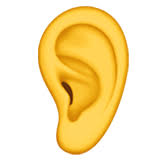**Challenge**: Close your eyes and listen to the sounds again. Can you visualize the striped image just by listening to the sounds? 

- How many stripes are there in total?

- How many black stripes are there? How many white?

- Can you tell which stripes are wide and which are thin?

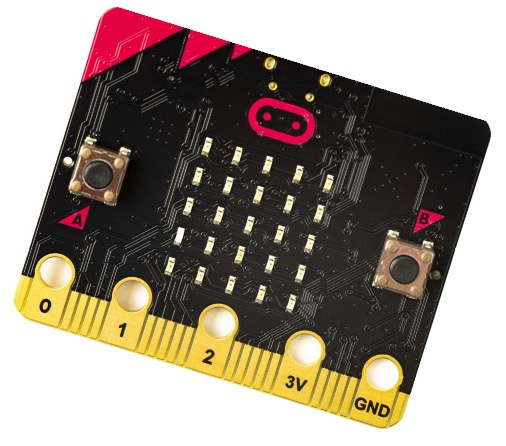**Challenge: **Grab a blank strip of paper and draw the striped image we generated with MATLAB. Copy it as closely as you can. Pull this image strip across the micro:bit device you built earlier. What are some differences you notice between how the micro:bit translates the stripes into sounds compared to MATLAB? Is one translation more accurate than the other?

## Part 2: Translate a grayscale image to sounds

The micro:bit device you built earlier can only read black and white images. That's because the light sensor in the micro:bit can only detect big changes in ambient light (like going between black and white). But MATLAB is more sensitive than the micro:bit, and can 'read' the image in more detail. 

When you open a digital picture on a computer, each individual point on an image is called a ***pixel***. Every pixel has its own brightness value. A digital picture is made up of rows of pixels. Just like you can cut a physical image into strips, you can divide a digital image into rows using MATLAB. And MATLAB can 'read' the brightness value of each individual pixel.

Let's use MATLAB to 'read' the brightness of the pixels along any row of an image. First, let's get an image to work with. You can either upload an image from your computer, load one of the example images, or take a picture with your webcam.

Use this button to upload an image:

 
% Create a file browser control
[fileName, pathName] = uigetfile({'*.jpg;*.png;*.gif', 'Image Files (*.jpg, *.png, *.gif)'}, 'Select an Image');

% Check if the user selected a file
if isequal(fileName, 0)
    disp('User canceled the file selection.');
else
    % Read and display the selected image
    img2 = imread(fullfile(pathName, fileName));
    img2 = imresize(img2,0.25);
    figure; imshow(img2);
    title('Uploaded Image');
end

*Or*, load one of the example images:

im_name = "cat1.jpg";
 
% Load an example image
cwd = pwd;
cd([cwd, '/ExampleImages/'])
img2 = imread(im_name);
cd ..
if contains(im_name, 'cat')
    img2 = imresize(img2, 0.2);
end
figure; imshow(img2)

*Or*, take a picture with your webcam. A camera preview will first pop up and it will stay up for 5 seconds while you prepare your best pose!

 
% Acquire an image with your webcam

if ~exist('webcam', 'file')
    error('Webcam support package is not installed. Please install it to use the webcam functionality.');
end

try
    cam = webcam;
    preview(cam)
    pause(5)
    img2 = snapshot(cam);
    img2 = imresize(img2, 0.25);
    figure; imshow(img2);
    clear cam
catch ME
    error('Error accessing webcam: %s. Try either uploading an image or using an example image instead.', ME.message);
end

Let's convert your image to grayscale. Click the button below:

 
num_rows = size(img2, 1); % Grab number of total rows
grayImg = rgb2gray(img2); % Convert the image to grayscale
figure; imshow(grayImg)
disp(['Your image has ', num2str(num_rows), ' rows.'])

Next, pick a row to get the brightness values of pixels in that row. You must pick a row number less than the total number of rows in the image.

Imagine that picking a row is like cutting out a specific strip of the image. A red line will appear on the image to show which row you selected.

row_number = 1;
% This line extracts the brightness values from the specified row of the striped image
graySignal = grayImg(row_number,:);

% Create a new figure to display the image with the row you selected
figure; imshow(grayImg); hold on; 
yline(row_number, 'r','LineWidth', 1.5);

Now, let's the plot the brightness values of the pixels along the row you selected.

 
% Create a new figure to plot the brightness values along the row of the
% image you selected
figure; plot(double(graySignal)/250, 'LineWidth', 1.25, 'Color', 'black');
title('Brightness Values of Pixels Along Row');
xlabel('Distance Along Row (pixels)');
ylabel('Brightness Value');

% Set the limits for the y-axis to make the plot clearer
ylim([-0.25 1.25]);
% Set y-ticks
yticks([0 1]);
yticklabels({'0 (Black)', '1 (White)'});

 **Reflect**. For black and white stripes, there were only two brightness values: 0 and 1. Since our image has varying shades of gray rather than just black and white, we now have a range of different brightness values between 0 and 1. Take a closer look at the row you selected in the image and try to map the brightness values to the image. Does the plot make sense? How well do the brightness values track the dark and bright pixels along the image row?

You might have noticed that the plot of the brightness values is bumpy, or jagged. Just like you can apply a filter to an image to blur sharp edges, we can also smooth out the brightness signal. ***Smoothing*** is a common step when scientists and engineers are trying to understand different signals (like brightness or sound signals). It helps to:

- **Make patterns clearer**: If you're trying to see the overall trend, like whether the brightness is generally increasing or decreasing, smoothing can help you ignore tiny random changes.

- **Reduces noise**: Smoothing removes random little wiggles that aren't important (usually called *noise*), so you can focus on the real signal.

- **Easier to analyze**: A smooth line is simpler to work with if you're using the signal to try and make predictions or decisions.

Think of it like brushing messy hair. The hair is still there, but now it's neat and easier to see the shape! An engineer designing a heart-rate monitor might smooth the raw sensor data so that sudden spikes caused by movement don’t confuse the system when detecting the actual heartbeat pattern.

Try it out here:

smooth_val =0;
% Smooth the brightness signal across the line
smoothedGraySignal = smooth(double(graySignal)/250, smooth_val); % Smooth the brightness signal

% Plot the average brightness values after smoothing, this will show a side
% by side comparison
figure; 
tiledlayout(1,2)

nexttile
plot(double(graySignal)/250, 'LineWidth',1.25, 'Color','black'); 
title('Before Smoothing');
xlabel('Pixels');
ylabel('Brightness Value');

% Set the limits for the y-axis to make the plot clearer
ylim([-0.25 1.25]);
% Set y-ticks
yticks([0 1]);
yticklabels({'0 (Black)', '1 (White)'});

nexttile
plot(smoothedGraySignal, 'LineWidth',1.25, 'Color','black'); 
title('After Smoothing');
xlabel('Pixels');
ylabel('Brightness Value');

% Set the limits for the y-axis to make the plot clearer
ylim([-0.25 1.25]);
% Set y-ticks
yticks([0 1]);
yticklabels({'0 (Black)', '1 (White)'});

   **Try **applying different amounts of smoothing. Do you think the smoothed signal provides a more useful representation of the brightness changes in the image? Is there such a thing as too much smoothing?

Let's use MATLAB to translate the smoothed brightness signal into sounds. You can choose to have one note played for each pixel. Or, you can choose to sample a smaller number of pixels and have a note played for every other, every 5th, every 10th, every 50th, every 100th pixel, and so on. This is called the ***sampling period***. 

When scientists and engineers analyze signals, it's important to choose the right sampling period. Sampling is like taking snapshots of the signal. If the sampling period is small, we take snapshots of the signal very often. If the sampling period is large, we wait longer between snapshots.

Why does sampling period matter?

- Short period (lots of snapshots) is great for accuracy and detail, but can take up a lot of space on the computer

- Long period (fewer snapshots) can save space and power, but might miss out on details

Sometimes less is more! Imagine you're filming a turtle walking.

- If you take a picture every second (short period), you'll have way too many pictures that look almost the same 

- If you take a picture every five seconds (long period), you'll still see the turtle moving without wasting computer space

First, let's ask MATLAB to count how many pixels are in the image row.

 
num_pix = size(grayImg,2); % This line of code counts how many pixels there are in one row of the image
disp([num2str(num_pix), ' pixels']);

If we played every single pixel as a sound lasting half a second, how long would it take to play every pixel in the row? Check your answer using the button below.

 
seconds = num_pix*0.5;
time = seconds/60;
disp(['It would take ', num2str(seconds), ' seconds (', num2str(time), ' minutes) to play ', num2str(num_pix), ' pixels.']);

  **Try** playing every single pixel as a sound. Is it worth the time it takes? If you want to stop the sounds before they're done playing, hit the 'Stop' button in the top toolstrip. It looks like this: 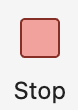

 
% Normalize all the brightness values to map to the range of
% frequencies
minBrightness = min(smoothedGraySignal); % Corresponds to the minimum brightness values
maxBrightness = max(smoothedGraySignal); % Corresponds to the maximum brightness values
% Find the lowest and highest notes in the octave 
minFreq = frequencies(1); % Corresponds to the lowest note
maxFreq = frequencies(end); % Corresponds to the highest note
normalizedBrightness = (smoothedGraySignal - minBrightness) / (maxBrightness - minBrightness);
soundSignal = minFreq + normalizedBrightness * (maxFreq - minFreq);

% Plot the brightness values again
figure; plot(smoothedGraySignal, 'LineWidth',1.25, 'Color','black'); 
hold on
title('Brightness Values of Pixels Along Row');
xlabel('Pixels');
ylim([-0.25 1.25]);
yticks([0 1]);
yticklabels({'0 (Black)', '1 (White)'});

% This loop will play each note corresponding to the pixel brightness.
for k=1:numel(soundSignal) 
    note_value=0:0.000125:0.5; 
    Fs = 14100; 
    
    % Make a sound wave using the frequency of the note we are currently on.
    a = sin(2*pi*soundSignal(k)*note_value); 
    
    % Draw a circle on the plot to show which pixel is being 'played'
    plot(k,smoothedGraySignal(k),'ro', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'black')

    % Now we play the sound and pause.
    sound(a, Fs)
    pause(1) 
end

  **Try**. Now, try using different sampling periods or use the default sampling period. Click 'Use default sampling period' to use the default. To stop the sounds before they're done playing or to change the sampling period, first hit the 'Stop' button.

sampling_period = 20;
% This line picks out every 'n'th pixel from the image row, based on the
% sampling period selected
nthGraySignal = smoothedGraySignal(1:sampling_period:end);
disp('Submitted! Thank you for selecting a sampling period. Scroll down to continue.')
 

 
% Normalize all the brightness values to map to the range of
% frequencies
minBrightness = min(nthGraySignal); % Corresponds to the minimum brightness values
maxBrightness = max(nthGraySignal); % Corresponds to the maximum brightness values
% Find the lowest and highest notes in the octave 
minFreq = frequencies(1); % Corresponds to the lowest note
maxFreq = frequencies(end); % Corresponds to the highest note
normalizedBrightness = (nthGraySignal - minBrightness) / (maxBrightness - minBrightness);
nthSoundSignal = minFreq + normalizedBrightness * (maxFreq - minFreq);

% Plot the brightness values again
figure; plot(smoothedGraySignal, 'LineWidth',1.25, 'Color','black'); 
hold on
title('Brightness Values of Pixels Along Row');
xlabel('Pixels');
ylim([-0.25 1.25]);
yticks([0 1]);
yticklabels({'0 (Black)', '1 (White)'});

% This loop will play each note corresponding to the pixel brightness
for k=1:numel(nthSoundSignal) 
    note_value=0:0.000125:0.5; 
    Fs = 14100; 
    
    % Make a sound wave using the frequency of the note we are currently on.
    a = sin(2*pi*nthSoundSignal(k)*note_value); 
    
    % Draw a circle on the plot to show which pixel is being 'played'
    if k == 1 
        plot(k,nthGraySignal(k),'ro', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'black')
    else
        plot((k-1)*sampling_period,nthGraySignal(k),'ro', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'black')
    end

    % Now we play the sound and pause.
    sound(a, Fs)
    pause(1) 
end

 **Reflect**. Is there an 'ideal' sampling period that saves time while still accurately representing the changing brightness values in the image? 

 **Challenge**: Close your eyes and listen carefully to the sounds. Can you visualize the changes in brightness in the image? How does choosing different sampling periods affect how you visualize the brightness changes in the image?

So far, we've only been translating a single row of the image into sounds. But you don't only read one line in a book - you read each line from left to right, from the top to the bottom of a page. A person who is visually impaired reads text with their fingers. The words are translated into raised dots, called Braille. You can use your fingers to trace each row of dots, just like your eyes would scan the words on a page.

Let's translate the whole image into sounds as if we're scanning the image from left to right, top to bottom. For simplicity, default sampling periods have been pre-selected to represent the image as an evenly distributed grid of pixels.

To stop the sounds before they're done playing or to change the sampling period, first hit the 'Stop' button.

 
% Smooth the signal across the whole image
dim = size(grayImg);
smoothedGrayImg = reshape(grayImg, 1, dim(1)*dim(2));
smoothedGrayImg = smooth(double(smoothedGrayImg)/250, 10);
smoothedGrayImg = reshape(smoothedGrayImg, dim(1), dim(2));

% Find the minimum and maximum brightness values
minBrightness = min(smoothedGrayImg(:));
maxBrightness = max(smoothedGrayImg(:)); 
% Find the lowest and highest notes in the octave 
minFreq = frequencies(1); 
maxFreq = frequencies(end); 

% Select default sampling periods
sample_rows = round(dim(1)/10);
sample_pixels = round(dim(2)/10);

% Plot the image again
figure; imshow(grayImg); hold on; 

% Prepare to play sounds for the smoothed image
note_value=0:0.000125:0.5; 
Fs = 14100; 
row_idx = 1:sample_rows:dim(1);
for k = 1:length(row_idx)
    nth_row_signal = smoothedGrayImg(row_idx(k), :);
    nth_row_signal = nth_row_signal(1:sample_pixels:end);
    normalizedBrightness = (nth_row_signal - minBrightness) / (maxBrightness - minBrightness);
    nthSoundSignal = minFreq + normalizedBrightness * (maxFreq - minFreq);

    % Play sound and plot marker for pixels along the row
    for jj = 1:length(nthSoundSignal)
        a = sin(2*pi*nthSoundSignal(jj)*note_value);
        % Draw a circle on the plot to show which pixel is being 'played'
        if k == 1 && jj == 1
            plot(jj, k,'ro', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'black')
        elseif k == 1 && jj > 1
            plot((jj-1)*sample_pixels,k,'ro', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'black')
        elseif k > 1 && jj == 1
            plot(jj, (k-1)*sample_rows,'ro', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'black')
        else
            plot((jj-1)*sample_pixels,(k-1)*sample_rows,'ro', 'MarkerFaceColor','r', 'MarkerEdgeColor', 'black')
        end

        % Now we play the sound and pause.
        sound(a, Fs)
        pause(1)
    end

end

## Part 3: Translate colors to sounds

The world around us isn't just in black and white or shades of gray. For a visually impaired person or someone who is colorblind, think about how difficult it could be to choose between a red or green apple or choosing what color clothes to wear.

The micro:bit light sensor can't detect different colors. It can only detect big changes in light (like going from bright white to dark black). But MATLAB can 'read' the colors of pixels in an image. Instead of translating pixel brightness into sounds, let's translate pixel colors into sounds.

First, choose which piano notes you want to represent different colors of the rainbow. Either use the drop down menus to pick notes to represent each color *or *use the default notes. Click 'Use default notes' to use them. Remember to pick **different** notes to represent each color. 

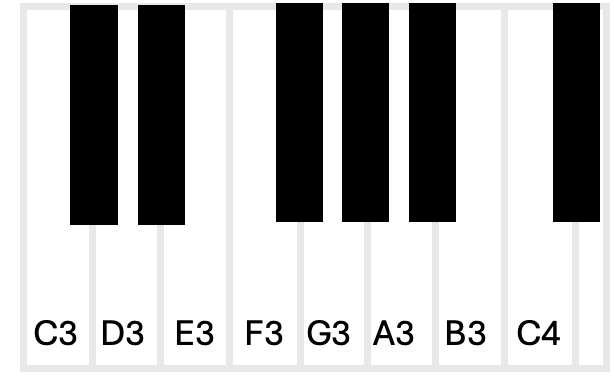

 
% Note: You may see a warning that the values assigned to these variables
% may be unused. These are variable assignments for the default notes that
% will be unused if the users decide to assign different notes below. 
red_freq = 261.63;
orange_freq = 293.66;
yellow_freq = 329.63;
blue_freq = 349.23;
green_freq = 392.00;
purple_freq = 440.00;
Fs = 14100; 
disp('Submitted! You have chosen to use the default notes. Scroll down to continue.')

red_freq = 261.63;  
note_value=0:0.000125:0.5; 
Fs = 14100; 
a = sin(2*pi*red_freq*note_value); 
sound(a, Fs)

orange_freq = 293.66;  
note_value=0:0.000125:0.5; 
Fs = 14100; 
a = sin(2*pi*orange_freq*note_value); 
sound(a, Fs)

yellow_freq = 329.63;  
note_value=0:0.000125:0.5; 
Fs = 14100; 
a = sin(2*pi*yellow_freq*note_value); 
sound(a, Fs)

green_freq = 349.23;  
note_value=0:0.000125:0.5; 
Fs = 14100; 
a = sin(2*pi*green_freq*note_value); 
sound(a, Fs)

blue_freq = 392.00;  
note_value=0:0.000125:0.5; 
Fs = 14100; 
a = sin(2*pi*blue_freq*note_value); 
sound(a, Fs)

purple_freq = 440.00;  
note_value=0:0.000125:0.5; 
Fs = 14100; 
a = sin(2*pi*purple_freq*note_value); 
sound(a, Fs)

Next, let's generate a random image of colored stripes.

 
% Parameters
nStripes = 5;
width = 100;
height = 200;

% Palette (RGB in [0,1]): red, orange, yellow, green, blue, violet
palette = [
    1.00, 0.00, 0.00, 1;   % red
    1.00, 0.65, 0.00, 2;   % orange
    1.00, 1.00, 0.00, 3;   % yellow
    0.00, 0.50, 0.00, 4;   % green
    0.00, 0.00, 1.00, 5;   % blue
    0.58, 0.00, 0.83, 6    % violet
];

% Define striped image with random colors
totalW = nStripes*width;
col_stripes = zeros(height, totalW, 3);
col_idx = zeros(1, nStripes);
xStart = 1;
for k = 1:nStripes
    rand_idx = randi(size(palette,1));
    color = palette(rand_idx, 1:3); % random color
    col_idx(k) = palette(rand_idx, 4);
    col_stripes(:, xStart:(xStart+width-1), 1) = color(1);
    col_stripes(:, xStart:(xStart+width-1), 2) = color(2);
    col_stripes(:, xStart:(xStart+width-1), 3) = color(3);
    xStart = xStart + width;
end

% Display the striped image
figure; 
imshow(col_stripes); hold on;
title('Randomly Colored Stripes');

Now, play the colors as sounds!

 
note_value=0:0.000125:0.5; 
Fs = 14100; 

% Plot striped image again
figure; 
imshow(col_stripes); hold on;

for k = 1:length(col_idx)
    % Generate the sound wave for each color
    if col_idx(k) == 1
        a = sin(2*pi*red_freq*note_value); 
    elseif col_idx(k) == 2
        a = sin(2*pi*orange_freq*note_value); 
    elseif col_idx(k) == 3
        a = sin(2*pi*yellow_freq*note_value); 
    elseif col_idx(k) == 4
        a = sin(2*pi*green_freq*note_value); 
    elseif col_idx(k) == 5
        a = sin(2*pi*blue_freq*note_value); 
    elseif col_idx(k) == 6
        a = sin(2*pi*purple_freq*note_value); 
    end

    % Plot marker to show which color is currently being played    
    plot((k*width)-(width/2), height/2, 'o', 'MarkerFaceColor', 'white', 'MarkerEdgeColor', 'black')
    
    % Play sound and pause
    sound(a, Fs)
    pause(1)
end

  **Try** generating a few more colored stripe images and playing the corresponding sounds. Practice memorizing which sound represents each color.

**Challenge**: Close your eyes and listen to the sounds again. Can you visualize the colors of each stripe?

- Pair up and have your partner generate a new colored stripe image and play the sounds. Guess what color each stripe is based on the sounds. Have your partner check your answers. Compete to see who can get the most correct!

**Challenge: **Grab a blank strip of paper and colored markers or pencils. Draw the colored striped image generated with MATLAB. Copy it as closely as you can. Pull the strip across the micro:bit device you built earlier. Can the micro:bit light sensor detect the different colors and play different sounds for each color?

- Close your eyes and listen to the sounds as you pull the strip through your micro:bit device. Can you guess the color of the stripes based on the sounds?

**Real-World Application**

Think about how a device that plays different sounds based on an object's color could help someone who is visually impaired or colorblind. For example, what if someone who was visually impaired wanted to know if they had any blue colored pencils? Or, pick out the orange peppers from a display at the grocery store? Load one of the real-world examples to simulate how such a device would function.

im_name = "peppers.png";
 
% Load an example image
cwd = pwd;
cd([cwd, '/ExampleImages/'])
img3 = imread(im_name);
cd ..
figure; imshow(img3)

 
% Parameters
note_value=0:0.000125:0.5; 
Fs = 14100; 
locs_peppers = [47, 218; 449, 149];
locs_pencils = [274, 47; 341, 42; 409, 32; 485, 20; 520, 152; 488, 345; 244, 257];

% Plot image again, play corresponding sounds and markers for colored objects in image
figure; imshow(img3); hold on
if contains(im_name, 'peppers')
    for k = 1:length(locs_peppers)
        plot(locs_peppers(k, 1), locs_peppers(k,2), 'o', 'MarkerFaceColor', 'white', 'MarkerEdgeColor', 'black', 'MarkerSize', 10);
        a = sin(2*pi*orange_freq*note_value); 
        sound(a, Fs)
        pause(1)
    end
elseif contains(im_name, 'pencils')
    for k = 1:length(locs_pencils)
        plot(locs_pencils(k, 1), locs_pencils(k,2), 'o', 'MarkerFaceColor', 'white', 'MarkerEdgeColor', 'black', 'MarkerSize', 10);
        a = sin(2*pi*blue_freq*note_value); 
        sound(a, Fs)
        pause(1)
    end
end

In MATLAB, we can simulate and test how our device functions using digital images. We can refine the sounds and make sure the device is functioning correctly. Then, when we are satisfied with the testing, we could download the code we created to a smartphone or a smart watch, and use our device in the real world. The beauty of simulating the device's function in MATLAB first is that we can troubleshoot it before we launch it on a device. Simulations like these can save scientists and engineers precious resources like time and supplies.

## Summary

Congratulations on finishing this MATLAB activity! Let's recap what you've learned and practiced throughout this activity.

- Visual signals (brightness values) can be translated into audio signals (sounds).

- Computers represent images as rows of *pixels*. Pixels have different brightness values

- *Smoothing* is a signal processing technique that can make signals clearer and easier to read.

- Choosing the right *sampling period* is important for balancing detail with minimal wasted time and space.

- The micro:bit light sensor can detect big changes in ambient light (like going from black to white). MATLAB can additionally detect small changes in shades of gray and detect different colors.

## **Future Learning**

To continue your learning, check out the following resources:

- New to MATLAB? Learn more about using MATLAB: [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted)

- Learn more about images and visual signals: [Pixels to Pictures ](https://www.mathworks.com/matlabcentral/fileexchange/179159-pixels-to-pictures)

- Learn more about making music and audio signals: [Bytes and Beats](https://www.mathworks.com/matlabcentral/fileexchange/174305-bytes-and-beats)

- Learn more about signal processing techniques: [Signal Processing Onramp](https://matlabacademy.mathworks.com/details/signal-processing-onramp/signalprocessing) and [Video Overview](https://www.youtube.com/watch?v=23rClDroHm0)

- Learn more about digital image manipulation: [Image Processing Onramp](https://matlabacademy.mathworks.com/details/image-processing-onramp/imageprocessing)